# Numeric Array

This widget combines multiple numeric edit fields that form elements of a 1-dimensional array. It is intended for small arrays typically 2 to 5 values. Optionally you may impose restrictions on the numerical range. You can also force the array to be `increasing` or `decreasing`. You can also set orientation as `horizontal` or `vertical`.

Create a figure with a grid layout:

figObj = uifigure("Position",[100 100 250 50]);
gridObj = uigridlayout(figObj,[1 1],"BackgroundColor",[.6 .8 1]);

Create and configure the widget:

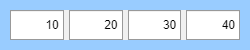

naWidget =   NumericArray with properties:

                  Value: [10 20 30 40]
                 Limits: [-Inf Inf]
    LowerLimitInclusive: on
    UpperLimitInclusive: on
            Restriction: none
            Orientation: horizontal
        ValueChangedFcn: @(src,evt)disp(evt)
               Position: [11 11 230 30]

  Show all properties


naWidget = wt.NumericArray(gridObj);
naWidget.ValueChangedFcn = @(src,evt)disp(evt);
naWidget.Value = [10 20 30 40]

Optionally, place some restrictions on the typed values:

naWidget.Tooltip = "Enter the increasing point values between 0 and 1000.";
naWidget.Limits = [0, 1000];
naWidget.LowerLimitInclusive = true;
naWidget.UpperLimitInclusive = true;
naWidget.Restriction = "increasing";

*Copyright 2024-2025 The MathWorks, Inc.*